format long;
warning('off','all')
clc; clear;

l = 0.01;
K_se = @(x,y) exp(-abs(x - y)^2 / (2*l^2));

G_cos = @(x,y) cos(10 * (x^2 + y)) * sin(10 * (x + y^2));

bessel = @(t) besselj(0,t);
G_bes = @(x,y) bessel(100*(x*y + y^2));

airy_c = @(t) airy(0,t);
G_airy = @(x,y) airy_c((-13)*((x^2)*y + y^2));

k = 100;

a = -1;
b = 1;

G_k_cos = HS_RSVD_approx(G_cos, K_se, k, a, b);
G_k_airy = HS_RSVD_approx(G_airy, K_se, k, a, b);
G_k_bes = HS_RSVD_approx(G_bes, K_se, k, a, b);

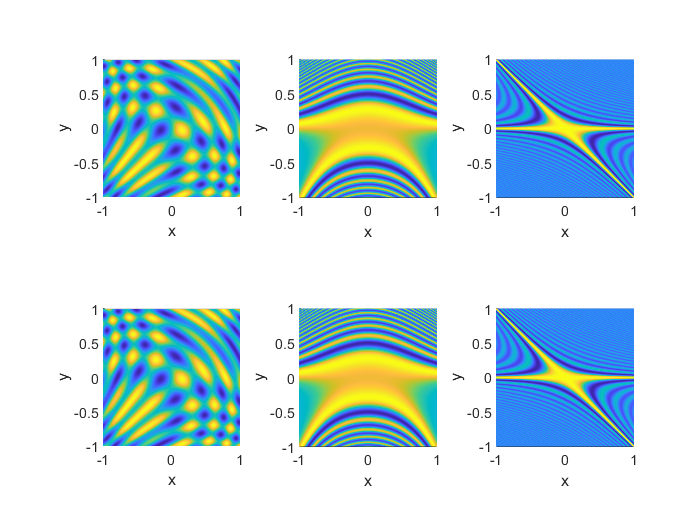

f1 = figure;

subplot(2,3,1)
plot(chebfun2(G_cos))
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

subplot(2,3,4)
plot(G_k_cos)
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

subplot(2,3,2)
plot(chebfun2(G_airy))
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

subplot(2,3,5)
plot(G_k_airy)
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

subplot(2,3,3)
plot(chebfun2(G_bes))
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

subplot(2,3,6)
plot(G_k_bes)
axis equal
xlabel("x")
ylabel("y")
view([0.90 90.00])

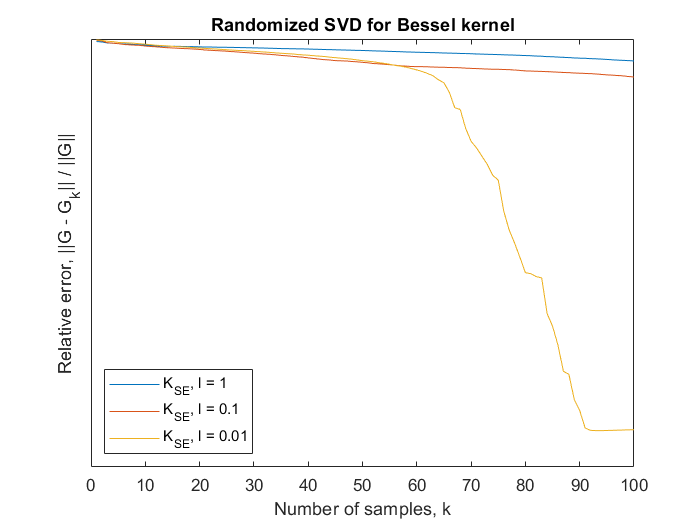

f2 = figure;

ls = [1, 0.1, 0.01];
for i = 1 : 3 
    l = ls(i);
    K_se = @(x,y) exp(-abs(x - y)^2 / (2*l^2));

    [n_samples, rel_errors] = get_errors(K_se, G_bes, k, a, b);
    semilogy(n_samples, rel_errors,'DisplayName',['K_{SE}, l = ', num2str(l)])
    legend('location', 'southwest')
    hold on
end
xlabel('Number of samples, k')
ylabel('Relative error, ||G - G_k|| / ||G||')
yticks([])
title('Randomized SVD for Bessel kernel')
hold off

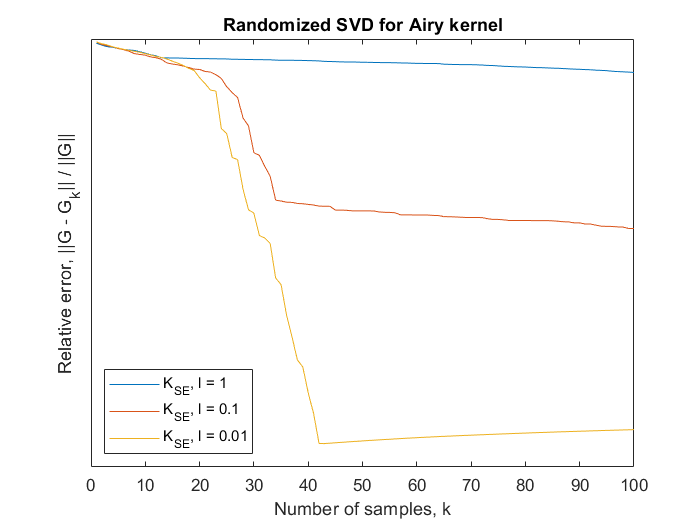

f3 = figure;

ls = [1, 0.1, 0.01];
for i = 1 : 3 
    l = ls(i);
    K_se = @(x,y) exp(-abs(x - y)^2 / (2*l^2));

    [n_samples, rel_errors] = get_errors(K_se, G_airy, k, a, b);
    semilogy(n_samples, rel_errors,'DisplayName',['K_{SE}, l = ', num2str(l)])
    legend('location', 'southwest')
    hold on
end
xlabel('Number of samples, k')
ylabel('Relative error, ||G - G_k|| / ||G||')
yticks([])
title('Randomized SVD for Airy kernel')
hold off

function [n_samples, rel_errors] = get_errors(K, G, k, a, b)
    n_samples = 1:k;
    
    [~, rel_errors] = HS_RSVD_approx(G, K, k, a, b);
end